%Add functions from shared folder
addpath('../Published')
filled_train = readtable('fillna_train.csv')

filled_train = 1458×81 table
    Var1    Id    MSSubClass    MSZoning    LotFrontage    LotArea    Street    Alley     LotShape    LandContour    LotConfig    LandSlope    Neighborhood    Condition1    Condition2    BldgType    HouseStyle    OverallQual    OverallCond    YearBuilt    YearRemodAdd    RoofStyle    RoofMatl     Exterior1st    Exterior2nd    MasVnrType    MasVnrArea    ExterQual    ExterCond    Foundation    BsmtQual    BsmtCond    

filled_train = filled_train(:,2:81)

filled_train = 1458×80 table
    Id    MSSubClass    MSZoning    LotFrontage    LotArea    Street    Alley     LotShape    LandContour    LotConfig    LandSlope    Neighborhood    Condition1    Condition2    BldgType    HouseStyle    OverallQual    OverallCond    YearBuilt    YearRemodAdd    RoofStyle    RoofMatl     Exterior1st    Exterior2nd    MasVnrType    MasVnrArea    ExterQual    ExterCond    Foundation    BsmtQual    BsmtCond    BsmtExposure   

%normalize the data

%I can't normalize non numeric fields!, so lets split it out

%[x mu sigma] = featureNormalize(filled_train)

**We want to use the following fields for our comparison:**

LotArea, Neighborhood, OverallCond,YearBuilt, ExterQual,CentralAir,GrLivArea,BedroomAbvGr,HalfBath,FullBath, (aha, I thought saleprice belonged here and was amazed at how accurate my model was.. oi!)

Of these, Neighborhood,CentralAir,ExterQual are text *(we'll try to assign numeric values to these later)*


numericFields = ["LotArea",'OverallCond','YearBuilt','GrLivArea','BedroomAbvGr','FullBath']

numericFields = 1×6 string array
    "LotArea"    "OverallCond"    "YearBuilt"    "GrLivArea"    "BedroomAbvGr"    "FullBath"



%get prices vector for later
prices = table2array(filled_train(:,'SalePrice'))

prices =       208500
      181500
      223500
      140000
      250000
      143000
      307000
      200000
      129900
      118000



textFields = ["Neighborhood","CentralAir","ExterQual"]

textFields = 1×3 string array
    "Neighborhood"    "CentralAir"    "ExterQual"


numeric_data = fillTable(filled_train,numericFields)

sz =         1458          80


sz =         1458           6


numeric_data =         8450           5        2003        1710           3           2
        9600           8        1976        1262           3           2
       11250           5        2001        1786           3           2
        9550           5        1915        1717           3           1
       14260           5        2000        2198           4           2
       14115           5        1993        1362           1           1
       10084           5        2004        1694           3           2
       10382           6        1973        2090           3           2
        6120           5        1931        1774           2           2
        7420           6        1939        1077           2           1


%uses dynamic table size slower but works with text
text_data = fillTableSlow(filled_train,textFields)

text_data = 1458×3 cell array
    {'CollgCr'}    {'Y'}    {'Gd'}
    {'Veenker'}    {'Y'}    {'TA'}
    {'CollgCr'}    {'Y'}    {'Gd'}
    {'Crawfor'}    {'Y'}    {'TA'}
    {'NoRidge'}    {'Y'}    {'Gd'}
    {'Mitchel'}    {'Y'}    {'TA'}
    {'Somerst'}    {'Y'}    {'Gd'}
    {'NWAmes' }    {'Y'}    {'TA'}
    {'OldTown'}    {'Y'}    {'TA'}
    {'BrkSide'}    {'Y'}    {'TA'}
    {'Sawyer' }    {'Y'}    {'TA'}
    {'NridgHt'}    {'Y'}    {'Ex'}
    {'Sawyer' }    {'Y'}    {'TA'}
    {'CollgCr'}    {'Y'}    {'Gd'}
    {'NAmes'  }    {'Y'}    {'TA'}
    {'BrkSide'}    {'Y'}    {'TA'}
    {'NAmes'  }    {'Y'}    {'TA'}
    {'Sawyer' }    {'Y'}    {'TA'}
    {'SawyerW'}    {'Y'}    {'TA'}
    {'NAmes'  }    {'Y'}    {'TA'}
    {'NridgHt'}    {'Y'}    {'Gd'}
    {'IDOTRR' }    {'Y'}    {'TA'}
    {'CollgCr'}    {'Y'}    {'Gd'}
    {'MeadowV'}    {'Y'}    {'TA'}
    {'Sawyer' }    {'Y'}    {'TA'}
    {'NridgHt'}    {'Y'}    {'Gd'}
    {'NAmes'  }    {'Y'}    {'TA'}
    {'NridgHt'}    {'Y'} 

**Let's look at the plot pre-normalization**

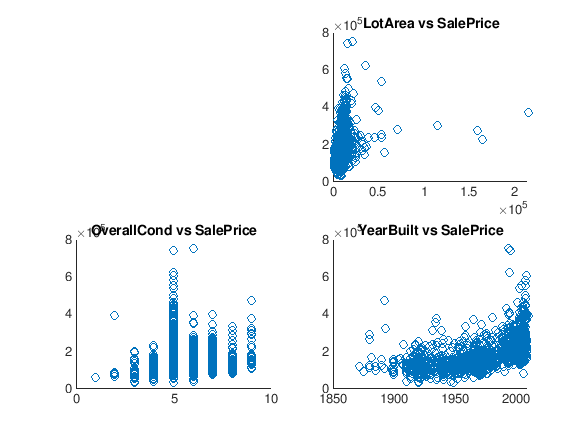

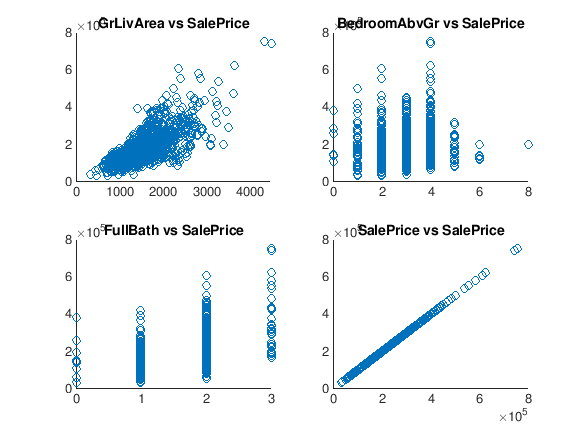

xField = 'LotArea';
yField = 'SalePrice';

index = 1;
graphFields = [numericFields  "SalePrice"];
graphData = [numeric_data prices];
for gf = graphFields
    sp = [2 2 mod(index,4)+1];
    %title('Sp')
    graphIt(graphData,index,gf,length(graphFields),graphFields(length(graphFields)),sp);
    index = index +1;
    if mod(index,4) == 0
        figure
    end
    
end

**Now, normalize the numeric data, ignoring text fields for now. (more on this later!)**

[normalized_numeric_data mu sigma] = featureNormalize(numeric_data);


**Let's see if our graphs improved...**

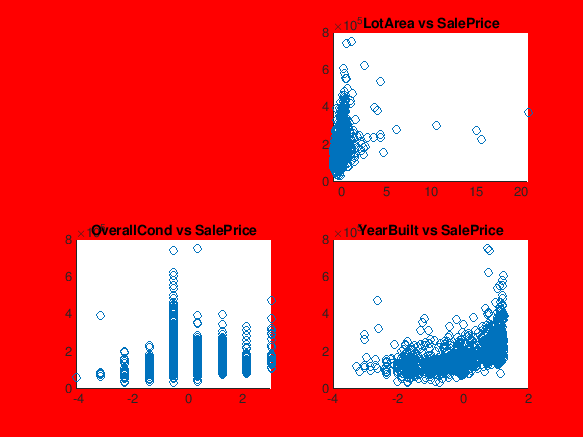

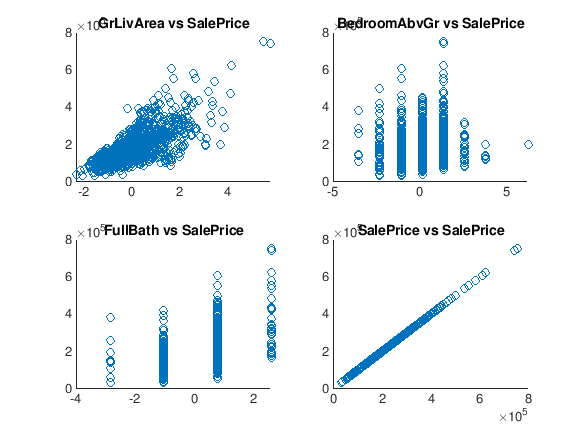

xField = 'LotArea';
yField = 'SalePrice';

index = 1;
graphFields = [numericFields  "SalePrice"];
graphData = [normalized_numeric_data prices];

figure ('Color','Red')
for gf = graphFields
    sp = [2 2 mod(index,4)+1];
    %title('Sp')
    graphIt(graphData,index,gf,length(graphFields),graphFields(length(graphFields)),sp);
    index = index +1;
    if mod(index,4) == 0
        figure
    end
    
end


%onePad the data for \theta 0

normalized_numeric_data = onePad(normalized_numeric_data)

normalized_numeric_data =                          1        -0.203864134597299        -0.517471847502635          1.05259827431749         0.392878002482192         0.163838210151875         0.793273490644681
                         1       -0.0872217888585376          2.17707798699323         0.158373584715388        -0.489222723052672         0.163838210151875         0.793273490644681
                         1        0.0801346202449026        -0.517471847502635         0.986359408421036         0.542520089849714         0.163838210151875         0.793273490644681
                         1       -0.0922931951950055        -0.517471847502635         -1.86191182512639         0.406660826318674         0.163838210151875         -1.02526856809737
                         1         0.385433281700269        -0.517471847502635          0.95323997547281          1.35373772136838           1.3888439045182         0.793273490644681
                         1         0.370726203324513       

**Perform gradient descent based on numeric values**


sz = size(normalized_numeric_data);
theta = zeros(sz(2),1);
alpha = 0.03;
iter = 20000;
[theta,jh] = gradientDescent(normalized_numeric_data,prices,theta,alpha,iter);

theta

theta =           180932.919067215
          9130.99801929549
          10953.0674781796
          33909.6806254555
          62291.6758401818
         -17727.3342645207
         -3441.53358179028


jh(iter-50:iter,:)

ans =           765788038.149524
          765788038.149524
          765788038.149524
          765788038.149524
          765788038.149524
          765788038.149524
          765788038.149524
          765788038.149524
          765788038.149524
          765788038.149524


%plot(jh)

**Now, calculate prices **

predictions = normalized_numeric_data*theta

predictions =           227935.340404355
          173243.581507602
          237603.850083107
          137241.116538886
          268084.482480806
          228959.515864068
          228609.310724442
          252477.705163369
          174482.170709654
          115279.576277742


prices

prices =       208500
      181500
      223500
      140000
      250000
      143000
      307000
      200000
      129900
      118000


%random samples...
guesses = [predictions prices]

guesses =           227935.340404355                    208500
          173243.581507602                    181500
          237603.850083107                    223500
          137241.116538886                    140000
          268084.482480806                    250000
          228959.515864068                    143000
          228609.310724442                    307000
          252477.705163369                    200000
          174482.170709654                    129900
          115279.576277742                    118000



%so far so good, right?

**So far so good, now to apply to test data!**

filled_test = readtable('test_fillna.csv')

filled_test = 1459×80 table
    Var1     Id     MSSubClass    MSZoning    LotFrontage    LotArea    Street    Alley     LotShape    LandContour    LotConfig    LandSlope    Neighborhood    Condition1    Condition2    BldgType    HouseStyle    OverallQual    OverallCond    YearBuilt    YearRemodAdd    RoofStyle    RoofMatl     Exterior1st    Exterior2nd    MasVnrType    MasVnrArea    ExterQual    ExterCond    Foundation    BsmtQual    BsmtCond    

filled_test = filled_test(:,2:80)

filled_test = 1459×79 table
     Id     MSSubClass    MSZoning    LotFrontage    LotArea    Street    Alley     LotShape    LandContour    LotConfig    LandSlope    Neighborhood    Condition1    Condition2    BldgType    HouseStyle    OverallQual    OverallCond    YearBuilt    YearRemodAdd    RoofStyle    RoofMatl     Exterior1st    Exterior2nd    MasVnrType    MasVnrArea    ExterQual    ExterCond    Foundation    BsmtQual    BsmtCond    BsmtExposure  

%extract id and remove from our dataset
test_ids = filled_test(:,1)

test_ids = 1459×1 table
     Id 
    ____

    1461
    1462
    1463
    1464
    1465
    1466
    1467
    1468
    1469
    1470
    1471
    1472
    1473
    1474
    1475
    1476


filled_test = filled_test(:,2:79)

filled_test = 1459×78 table
    MSSubClass    MSZoning    LotFrontage    LotArea    Street    Alley     LotShape    LandContour    LotConfig    LandSlope    Neighborhood    Condition1    Condition2    BldgType    HouseStyle    OverallQual    OverallCond    YearBuilt    YearRemodAdd    RoofStyle    RoofMatl     Exterior1st    Exterior2nd    MasVnrType    MasVnrArea    ExterQual    ExterCond    Foundation    BsmtQual    BsmtCond    BsmtExposure    BsmtFinType1


%numericFields = ["LotArea",'OverallCond','YearBuilt','GrLivArea','BedroomAbvGr','FullBath']
%textFields = ["Neighborhood","CentralAir","ExterQual"]
%get prices vector for later
%prices = table2array(filled_train(:,'SalePrice'))


test_numeric_data = fillTable(filled_test,numericFields)

sz =         1459          78


sz =         1459           6


test_numeric_data =        11622           6        1961         896           2           1
       14267           6        1958        1329           3           1
       13830           5        1997        1629           3           2
        9978           6        1998        1604           3           2
        5005           5        1992        1280           2           2
       10000           5        1993        1655           3           2
        7980           7        1992        1187           3           2
        8402           5        1998        1465           3           2
       10176           5        1990        1341           2           1
        8400           5        1970         882           2           1


%uses dynamic table size slower but works with text
test_text_data = fillTableSlow(filled_test,textFields)

test_text_data = 1459×3 cell array
    {'NAmes'  }    {'Y'}    {'TA'}
    {'NAmes'  }    {'Y'}    {'TA'}
    {'Gilbert'}    {'Y'}    {'TA'}
    {'Gilbert'}    {'Y'}    {'TA'}
    {'StoneBr'}    {'Y'}    {'Gd'}
    {'Gilbert'}    {'Y'}    {'TA'}
    {'Gilbert'}    {'Y'}    {'TA'}
    {'Gilbert'}    {'Y'}    {'TA'}
    {'Gilbert'}    {'Y'}    {'TA'}
    {'NAmes'  }    {'Y'}    {'TA'}
    {'NAmes'  }    {'Y'}    {'Gd'}
    {'BrDale' }    {'Y'}    {'TA'}
    {'BrDale' }    {'Y'}    {'TA'}
    {'NPkVill'}    {'Y'}    {'TA'}
    {'NPkVill'}    {'Y'}    {'TA'}
    {'NridgHt'}    {'Y'}    {'Ex'}
    {'NridgHt'}    {'Y'}    {'Gd'}
    {'NridgHt'}    {'Y'}    {'Gd'}
    {'NridgHt'}    {'Y'}    {'Gd'}
    {'NridgHt'}    {'Y'}    {'Ex'}
    {'NridgHt'}    {'Y'}    {'Gd'}
    {'NridgHt'}    {'Y'}    {'Gd'}
    {'Gilbert'}    {'Y'}    {'Gd'}
    {'Blmngtn'}    {'Y'}    {'Gd'}
    {'Gilbert'}    {'Y'}    {'Gd'}
    {'Gilbert'}    {'Y'}    {'Gd'}
    {'NoRidge'}    {'Y'}    {'Gd'}
    {'Somerst'}    {

%now, renormalize the data
normalized_test_data = reNormalize(test_numeric_data,mu,sigma);

XNorm =          0.117865883388224         0.380711430662653        -0.338417909508001         -1.20986751221732         -1.06116748421445         -1.02526856809737
         0.386143278587375         0.380711430662653        -0.437776208352679        -0.357301409189199         0.163838210151875         -1.02526856809737
         0.341819187206646        -0.517471847502635         0.853881676628133         0.233391040945755         0.163838210151875         0.793273490644681
       -0.0488819569548404         0.380711430662653         0.887001109576358         0.184166670101175         0.163838210151875         0.793273490644681
        -0.553284031179936        -0.517471847502635         0.688284511887003        -0.453781176044575         -1.06116748421445         0.793273490644681
       -0.0466505381667945        -0.517471847502635         0.721403944835229         0.284584386624117         0.163838210151875         0.793273490644681
        -0.251535354160097          1.278894708827

normalized_test_data = onePad(normalized_test_data)

normalized_test_data =                          1         0.117865883388224         0.380711430662653        -0.338417909508001         -1.20986751221732         -1.06116748421445         -1.02526856809737
                         1         0.386143278587375         0.380711430662653        -0.437776208352679        -0.357301409189199         0.163838210151875         -1.02526856809737
                         1         0.341819187206646        -0.517471847502635         0.853881676628133         0.233391040945755         0.163838210151875         0.793273490644681
                         1       -0.0488819569548404         0.380711430662653         0.887001109576358         0.184166670101175         0.163838210151875         0.793273490644681
                         1        -0.553284031179936        -0.517471847502635         0.688284511887003        -0.453781176044575         -1.06116748421445         0.793273490644681
                         1       -0.0466505381667945        -0


%now calculate dem prices
test_prices = normalized_test_data * theta

test_prices =            121678.95900555
          152151.077090605
          216244.847263524
           220572.01878525
          181367.291013351
          211394.372689672
           170675.67725884
          192226.106903882
          197650.491123445
          117247.587948612


All input arguments must be tables.

**Now, write to CSV and submit for score**

format long
test_results = [table2array(test_ids)  test_prices]

test_results = 	1.0e+05 *

   0.014610000000000   1.216789590055498
   0.014620000000000   1.521510770906049
   0.014630000000000   2.162448472635245
   0.014640000000000   2.205720187852496
   0.014650000000000   1.813672910133514
   0.014660000000000   2.113943726896722
   0.014670000000000   1.706756772588401
   0.014680000000000   1.922261069038822
   0.014690000000000   1.976504911234452
   0.014700000000000   1.172475879486116




%unfortunately dlmw write forces scientific notation, so lets do it ourselves
 fid = fopen('results-fp-tk2.csv', 'w') ;
 fprintf(fid,"Id,SalePrice\n")

ans =     13


     for  index =  1:length(test_results)
         fprintf(fid, '%i,', test_results(index,1));
         fprintf(fid, '%0.9f\n', test_results(index,2));
     end
 fclose(fid) ;

**This version scored 0.22X,. which is .. not great. The lack of neighborhood is really hurting!**